## Bergman Minimal Model

In 1979 Bergman’s minimal model (BMM) as a dynamic model of plasma glucose concentration was built as a powerful tool to estimate insulin sensitivity based on IVGTT. Let's show how to easily use it in 5 simple steps.

### 1. Preprocess the data from the IVGTT

[t, g, i] = importfile('IVGTT_AP.csv');

### 2. Plot data from the IVGTT

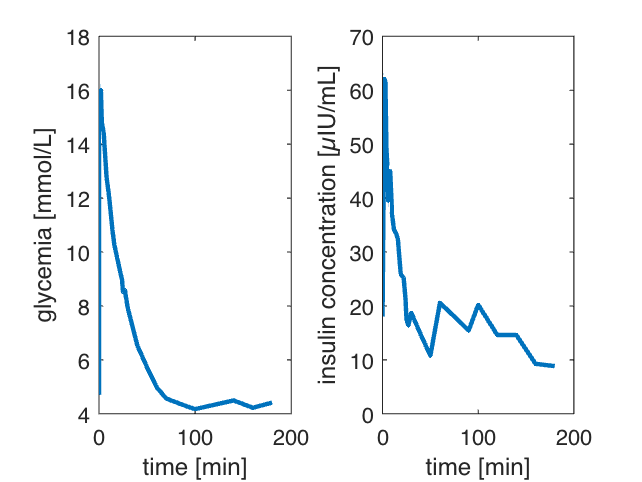

figure
subplot(121); plot(t, g, '-','Linewidth',2); hold on
xlabel('time [min]'); ylabel('glycemia [mmol/L]')
subplot(122); plot(t, i, '-','Linewidth',2)
xlabel('time [min]'); ylabel('insulin concentration [µIU/mL]')

### 3. Compile a simulation scheme of BMM

We've got you covered

open_system('bmm_sim.slx')

### 4. Implement a identification method of Bergman model parameters

Initialize optimized variables

p2 = 1e-4;      % [1/min]
Si = 10e-1;     % [mL/(µIU*min)]
Sg = 3.6e-2;    % [1/min]
Ib = i(1);      % [µIU/mL]
Gb = g(1);      % [mmol/L]
G0 = Gb;        % [mmol/L]
X0 = 0;         % [1/min]

x0 = [p2 Si Sg G0 X0 Ib Gb];

Initialize input

input_sim.time = t;
input_sim.signals.values = i;
input_sim.signals.dimensions = 1;

Set optimization options

opts = optimset('Display', 'iter', 'MaxIter', 250);

Run identification

[x_opt, fval, exitflag, output] = ...
    fminsearch(@objectiveFcn, x0, opts, g(2:end), t(2:end), 1)

Error using objectiveFcn (line 10)
Invalid Simulink object name: bmm_sim/BMM/Gain_Sg.

Error in fminsearch (line 201)
fv(:,1) = funfcn(x,varargin{:});

Caused by:
    Error using objectiveFcn (

### 5. Evaluation of results

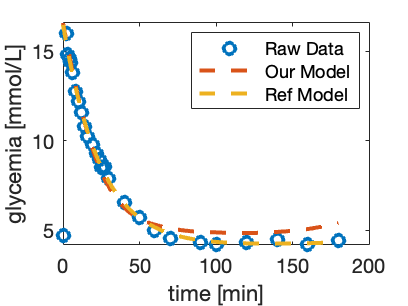

figure
plot(t, g, 'o','Linewidth',2); hold on

out = sim('bmm_sim.slx');
plot(out.OutData(:,1),out.OutData(:,2), '--','Linewidth',2); hold on

p2 = 1.0744e-4; Si = 0.0113; Sg = 0.0394;
G0 = 16.4964; X0 = 0.0009;
Ib = 34.2943; Gb = 4.0957;

set_param('bmm_sim/BMM/Gain_Sg', 'Gain', num2str(Sg));
set_param('bmm_sim/BMM/Gain_Sip2', 'Gain', num2str(Si*p2))
set_param('bmm_sim/BMM/Gain_p2', 'Gain', num2str(p2))
set_param('bmm_sim/BMM/Integrator_G', ...
          'InitialCondition', num2str(G0))
set_param('bmm_sim/BMM/Integrator_X', ...
          'InitialCondition', num2str(X0))
set_param('bmm_sim/Ib', 'Value', num2str(Ib))
set_param('bmm_sim/Gb', 'Value', num2str(Gb))

out_ref = sim('bmm_sim.slx');
plot(out_ref.OutData(:,1), ...
     out_ref.OutData(:,2), ...
     '--','Linewidth',2); hold on

xlabel('time [min]'); ylabel('glycemia [mmol/L]')
legend('Raw Data', 'Our Model', 'Ref Model')